% Sarrus Linkage: Kinematics Analysis and 3D Animation
clear; clc; close all;

% ========================================================================
% PART 1: KINEMATIC ANALYSIS & PLOTTING
% =========================================================================
disp('Starting Kinematic Analysis...');

Starting Kinematic Analysis...



% 1.Symbolic Derivation
syms t_sym L_sym real
syms theta_sym(t_sym)

z_sym = 2 * L_sym * sin(theta_sym);          % Position
v_sym = diff(z_sym, t_sym);                  % Velocity
a_sym = diff(v_sym, t_sym);                  % Acceleration

disp('--- Governing Equations ---');

--- Governing Equations ---


disp('Position (z):'); pretty(z_sym)

Position (z):


$$2\,L_{\mathrm{sym}}\,\sin\left(\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)\right)$$

disp('Velocity (v):'); pretty(v_sym)

Velocity (v):


$$2\,L_{\mathrm{sym}}\,\cos\left(\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)\right)\,\frac{\partial }{\partial t_{\mathrm{sym}}}\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)$$

disp('Acceleration (a):'); pretty(a_sym)

Acceleration (a):


$$2\,L_{\mathrm{sym}}\,\cos\left(\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)\right)\,\frac{\partial^{2}}{\partial {t_{\mathrm{sym}}}^{2}}\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)-2\,L_{\mathrm{sym}}\,\sin\left(\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)\right)\,{\left(\frac{\partial }{\partial t_{\mathrm{sym}}}\theta_{\mathrm{sym}}\left(t_{\mathrm{sym}}\right)\right)}^{2}$$

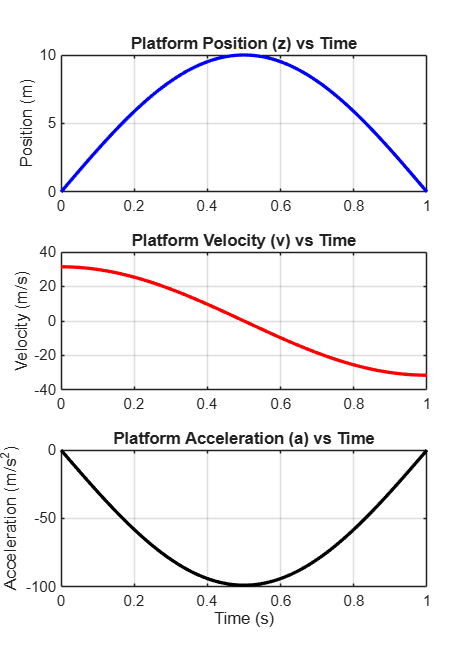


% 2.Numerical Parameters 
L_num = 5;                          % ความยาวของแขนกล (L)
omega = pi;                         % ความเร็วเชิงมุมคงที่ (rad/s)
t_vec = linspace(0, 1, 200);        % ช่วงเวลา 1 วินาที (200 จุด)
theta_kinematics = omega * t_vec;   % มุม theta เปลี่ยนตามเวลา

% คำนวณค่าเพื่อพล็อตกราฟ
z_num = 2 * L_num * sin(theta_kinematics);
v_num = 2 * L_num * omega * cos(theta_kinematics);
a_num = -2 * L_num * omega^2 * sin(theta_kinematics);

% 3.Plot Kinematics Figure
fig1 = figure('Name', 'Sarrus Linkage: Kinematics Plots', 'Color', 'w', 'Position', [50, 100, 500, 700]);

subplot(3,1,1);
plot(t_vec, z_num, 'b', 'LineWidth', 2);
title('Platform Position (z) vs Time');
ylabel('Position (m)');
grid on;

subplot(3,1,2);
plot(t_vec, v_num, 'r', 'LineWidth', 2);
title('Platform Velocity (v) vs Time');
ylabel('Velocity (m/s)');
grid on;

subplot(3,1,3);
plot(t_vec, a_num, 'k', 'LineWidth', 2);
title('Platform Acceleration (a) vs Time');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
grid on;


disp('Plots generated. Starting 3D Animation...');

Plots generated. Starting 3D Animation...


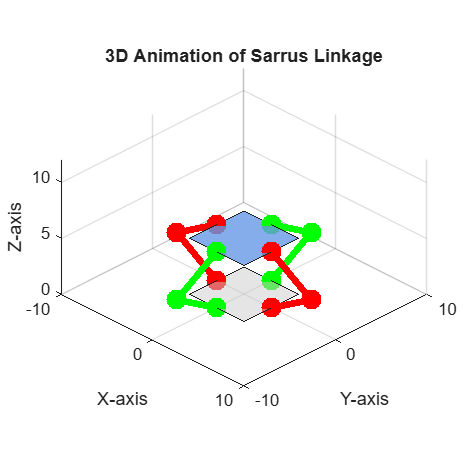

pause(2);


% ========================================================================
% PART 2: 3D ANIMATION
% =========================================================================
% พารามิเตอร์เพิ่มเติมสำหรับ 3D
W = 3;               % ความกว้างครึ่งหนึ่งของฐาน
theta_min = pi/6;    % มุมพับที่แคบที่สุด
theta_max = pi/2.2;  % มุมกางที่กว้างที่สุด
frames = 100;        % จำนวนเฟรมต่อรอบ

% สร้างเวกเตอร์มุม theta ที่แกว่งไป-กลับสำหรับการจำลองภาพเคลื่อนไหว
theta_anim = [linspace(theta_min, theta_max, frames), linspace(theta_max, theta_min, frames)];

% สร้าง Figure ใหม่สำหรับ 3D Animation
fig2 = figure('Name', 'Sarrus Linkage: 3D Animation', 'Color', 'w', 'Position', [600, 100, 700, 700]);
ax = axes('Parent', fig2);
hold(ax, 'on');
grid(ax, 'on');
view(ax, 45, 30);   % ปรับมุมมอง 3 มิติ (Azimuth 45, Elevation 30)
axis(ax, 'equal');

% ขอบเขตกราฟ 3 มิติ
xlim(ax, [-10, 10]);
ylim(ax, [-10, 10]);
zlim(ax, [0, 12]);
xlabel(ax, 'X-axis');
ylabel(ax, 'Y-axis');
zlabel(ax, 'Z-axis');
title(ax, '3D Animation of Sarrus Linkage');

% วาดฐานล่าง (สีเทา)
base_x = [-W W W -W];
base_y = [-W -W W W];
base_z = [0 0 0 0];
patch(ax, base_x, base_y, base_z, [0.8 0.8 0.8], 'FaceAlpha', 0.5);

% สร้าง Patch สำหรับแพลตฟอร์มด้านบน (สีฟ้า)
top_plat = patch(ax, base_x, base_y, base_z, [0.4 0.6 0.9], 'FaceAlpha', 0.8);

% สร้างเส้นแขนกล (Line Objects)
arm1_right = plot3(ax, 0,0,0, '-o', 'Color', 'r', 'LineWidth', 4, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
arm1_left  = plot3(ax, 0,0,0, '-o', 'Color', 'r', 'LineWidth', 4, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
arm2_front = plot3(ax, 0,0,0, '-o', 'Color', 'g', 'LineWidth', 4, 'MarkerSize', 8, 'MarkerFaceColor', 'g');
arm2_back  = plot3(ax, 0,0,0, '-o', 'Color', 'g', 'LineWidth', 4, 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Animation Loop (รัน 3 รอบ)
for loop = 1:3
    for k = 1:length(theta_anim)
        th = theta_anim(k);

        % ความสูงของแพลตฟอร์ม
        z_top = 2 * L_num * sin(th);
        top_plat.ZData = [z_top z_top z_top z_top];

        % อัปเดตแขนสีแดง (แกน X)
        x_r = [W, W + L_num*cos(th), W];
        y_r = [0, 0, 0];
        z_r = [0, L_num*sin(th), z_top];
        set(arm1_right, 'XData', x_r, 'YData', y_r, 'ZData', z_r);

        x_l = [-W, -W - L_num*cos(th), -W];
        y_l = [0, 0, 0];
        z_l = [0, L_num*sin(th), z_top];
        set(arm1_left, 'XData', x_l, 'YData', y_l, 'ZData', z_l);

        % อัปเดตแขนสีเขียว (แกน Y)
        x_f = [0, 0, 0];
        y_f = [-W, -W - L_num*cos(th), -W];
        z_f = [0, L_num*sin(th), z_top];
        set(arm2_front, 'XData', x_f, 'YData', y_f, 'ZData', z_f);

        x_b = [0, 0, 0];
        y_b = [W, W + L_num*cos(th), W];
        z_b = [0, L_num*sin(th), z_top];
        set(arm2_back, 'XData', x_b, 'YData', y_b, 'ZData', z_b);

        drawnow;
        pause(0.015);
    end
end

disp('Animation Complete.');

Animation Complete.
